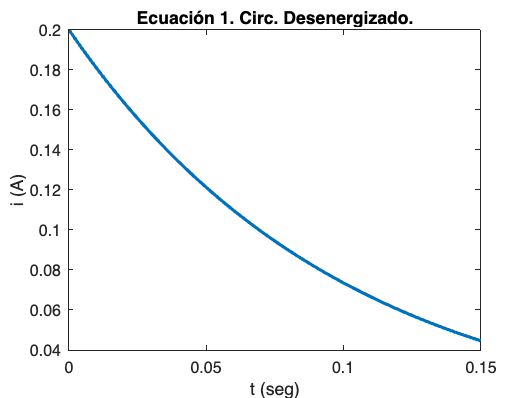

% Datos del Circuito.

Vg = 1.0;
R = 5.0;
L = 0.5;

% Ecuación 1. Desenergizado.

t1 = linspace(0.0, 0.15);
A = (Vg/R);
y1 = (A)*(exp(-(R/L)*t1));

plot(t1, y1, 'LineStyle','-','LineWidth', 2);

title("Ecuación 1. Circ. Desenergizado.");
xlabel("t (seg)");
ylabel("i (A)");

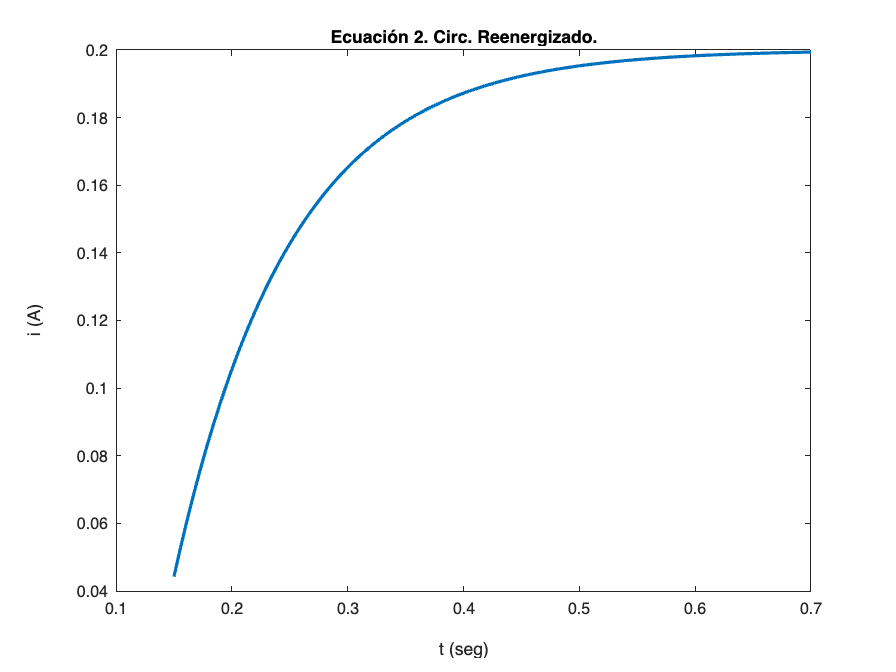


% Ecuación 2. Reenergizado.

t2 = linspace(0.15, 0.70);
b=0.04426;
A2=(b-A)/(exp(-(R/L)*0.15));
y2=(Vg/R)+A2*exp(-(R/L)*t2);

plot(t2, y2, 'LineStyle', '-', 'LineWidth', 2);

title("Ecuación 2. Circ. Reenergizado.");
xlabel("t (seg)");
ylabel("i (A)");

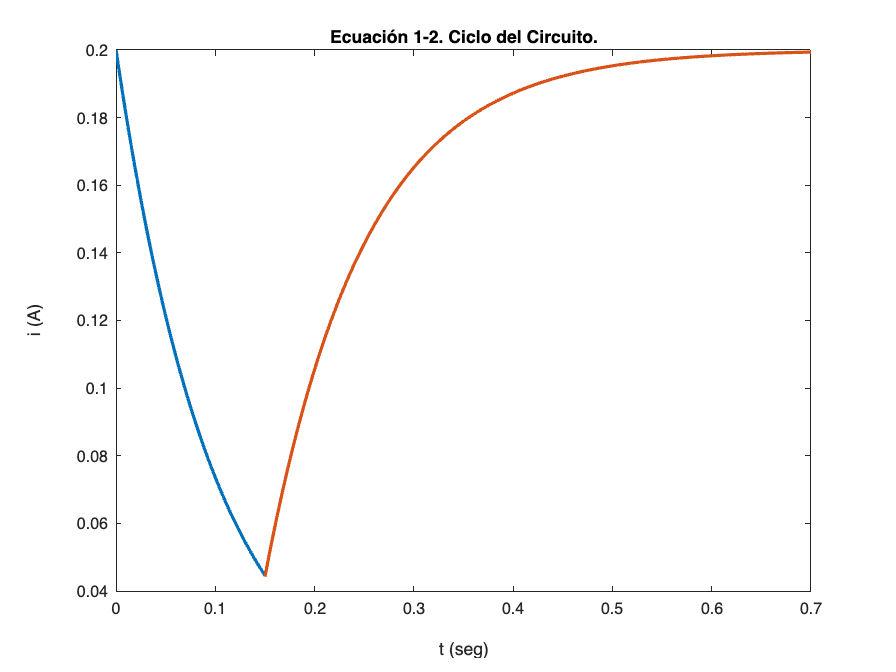


% Gráfico Ecuación 1 y 2.

plot(t1, y1, t2, y2, 'LineStyle', '-', 'LineWidth', 2);

title("Ecuación 1-2. Ciclo del Circuito.");
xlabel("t (seg)");
ylabel("i (A)");

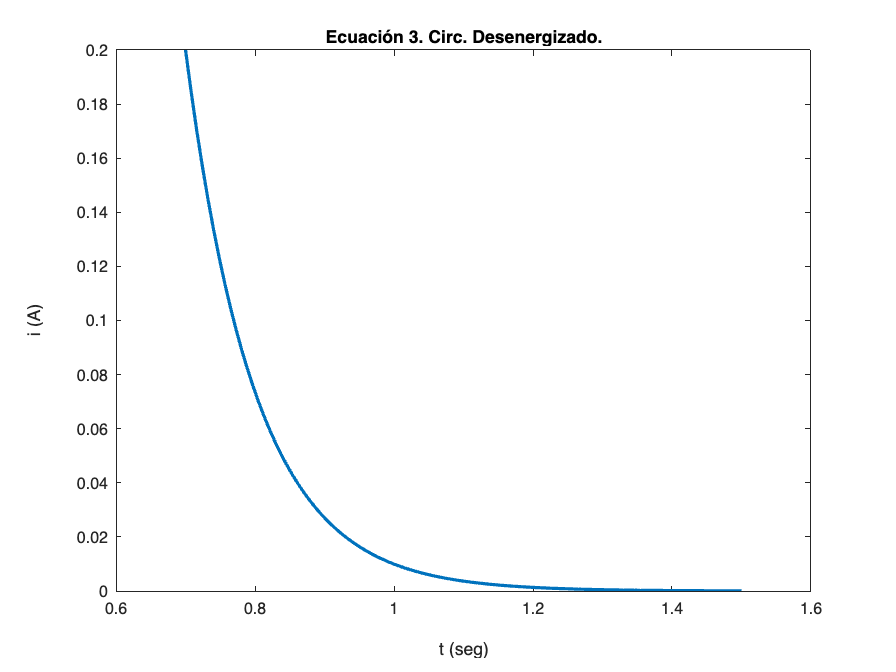


% Ecuación 3. Desenergizado.

t3 = linspace(0.7,1.5);
A3=A/(exp(-(R/L)*0.7));
y3=A3*exp(-(R/L)*t3);

plot(t3, y3, 'LineStyle', '-', 'LineWidth', 2);

title("Ecuación 3. Circ. Desenergizado.");
xlabel("t (seg)");
ylabel("i (A)");

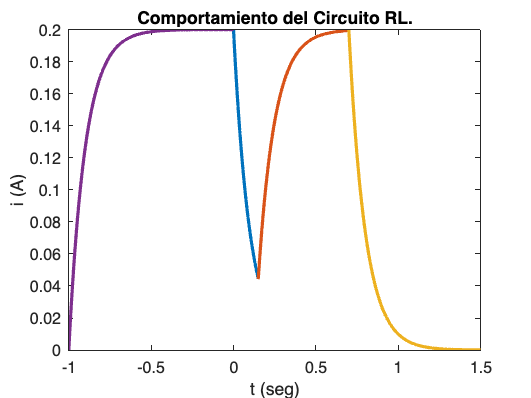


% Gráfico Ecuación 1-3.

plot(t1, y1, t2, y2, 'LineStyle', '-', 'LineWidth', 2);
hold on
plot(t3,y3,'LineWidth',2)

title("Ecuación 1-3. Comportamiento del Circuito");
xlabel("t (seg)");
ylabel("i (A)");

% Ecuación para energizar el circuito C.I = O

t4 = linspace(-1,0);
b1 = 0;
A2 = (b1-A)/(exp(-(R/L)*-1));
y4=(Vg/R)+A2*exp(-(R/L)*t4);

plot(t4, y4, 'LineStyle', '-', 'LineWidth', 2);

title("Comportamiento del Circuito RL.");
xlabel("t (seg)");
ylabel("i (A)");